# Step 3: Synthetic Sensors

Creates a simplified sensor model for the drone. The trajectory generated in Step 2 is treated as the **ground-truth motion**, and synthetic measurements are generated for a camera and IMU by adding realistic measurement noise and sensor biases.


$$\text{Ground Truth}
\rightarrow
\text{Sensor Model}
\rightarrow
\text{Noisy Measurements}$$


clc;
clear;
close all;

%% STEP 3: SYNTHETIC SENSOR GENERATION

% Load trajectory generated in Step 2
load('drone_toy_model.mat');


%% 1. Use Step 2 Trajectory as Ground Truth

% The trajectory generated in Step 2 is treated as
% the true motion of the drone.

numSamples = length(t);

p_true = pd

p_true =          0         0         0
    0.0000         0    0.0000
    0.0000         0    0.0000
    0.0001         0    0.0000
    0.0002         0    0.0001
    0.0003         0    0.0002
    0.0005         0    0.0003
    0.0008         0    0.0004
    0.0012         0    0.0006
    0.0017         0    0.0009
    0.0023         0    0.0012
    0.0031         0    0.0015
    0.0039         0    0.0020
    0.0050         0    0.0025
    0.0062         0    0.0031


v_true = vd;
a_true = ad;


$$\mathbf{p}_{true}(t)=\mathbf{p}_d(t)$$



$$\mathbf{v}_{true}(t)=\mathbf{v}_d(t)
$$



$$\mathbf{a}_{true}(t)=\mathbf{a}_d(t)$$


g = [0; 0; -9.81];

Gravity is important for the IMU model because an accelerometer does not directly measure world-frame acceleration. It measures **specific force** in its own body frame.


$$\mathbf{g} =
[0\;0\;-9.81]^T
\ \mathrm{m/s^2}$$


The negative z-direction indicates that gravity acts downward in the chosen world coordinate system.

%% 3. Generate True Orientation

R_true = zeros(3,3,numSamples);

for k = 1:numSamples

    % -----------------------------------------------------
    % Desired yaw
    % -----------------------------------------------------

    if norm(v_true(k,1:2)) > 1e-4

        yaw = atan2( ...
            v_true(k,2), ...
            v_true(k,1));

    else

        yaw = 0;

    end

If the horizontal velocity is sufficiently large, the yaw is calculated as *desired yaw*


$$\psi = \\{atan2}(v_y,v_x)$$


If the horizontal velocity is almost zero, the code sets


$$\psi = 0$$



    % -----------------------------------------------------
    % Approximate pitch
    % -----------------------------------------------------

    pitch = atan2( ...
        a_true(k,1), ...
        9.81);


    % -----------------------------------------------------
    % Approximate roll
    % -----------------------------------------------------

    roll = -atan2( ...
        a_true(k,2), ...
        9.81);



$$\theta = \,{atan2}(a_x,9.81)$$



$$\phi = -\,{atan2}(a_y,9.81)$$


    % -----------------------------------------------------
    % Rotation about X
    % -----------------------------------------------------

    Rx = [
        1 0 0;
        0 cos(roll) -sin(roll);
        0 sin(roll) cos(roll)
    ];


    % -----------------------------------------------------
    % Rotation about Y
    % -----------------------------------------------------

    Ry = [
        cos(pitch) 0 sin(pitch);
        0 1 0;
        -sin(pitch) 0 cos(pitch)
    ];


    % -----------------------------------------------------
    % Rotation about Z
    % -----------------------------------------------------

    Rz = [
        cos(yaw) -sin(yaw) 0;
        sin(yaw) cos(yaw) 0;
        0 0 1
    ];


    % -----------------------------------------------------
    % Body-to-world rotation
    % -----------------------------------------------------

    R_true(:,:,k) = Rz * Ry * Rx;

end

## True SO(3) Orientation


$$R_{true}=R_zR_yR_x$$



$$R_{true}(t) \in SO(3)$$



$$R^TR=I,\qquad \det(R)=1$$


## True Angular Velocity

First, the relative rotation between two consecutive time steps is calculated as


$$R_{rel}=R_k^TR_{k+1}$$


The `logSO3()` function then converts this rotation matrix into a rotation vector:


$$\Delta\,{\theta}
=
\log(R_{rel})$$


The angular velocity is approximated by dividing the rotation vector by the simulation timestep:


$$\,{\omega}_{true,k}
=
\frac{\Delta\,{\theta}}{\Delta t}$$



%% 4. Calculate True Angular Velocity

omega_true = zeros(numSamples,3);

for k = 1:numSamples-1

    % Relative rotation between consecutive samples
    R_relative = ...
        R_true(:,:,k)' * ...
        R_true(:,:,k+1);


    % Rotation vector
    delta_theta = ...
        logSO3(R_relative);


    % Angular velocity
    omega_true(k,:) = ...
        (delta_theta / dt)';

end

These parameters control how far the synthetic measurements deviate from the ground truth.

Camera position noise:


$$\sigma_p = 0.05\ \mathrm{m}$$


Camera orientation noise:


$$\sigma_R = 1^\circ$$


Accelerometer noise:


$$\sigma_a = 0.10\ \mathrm{m/s^2}$$


Gyroscope noise:


$$\sigma_\omega = 0.01\ \mathrm{rad/s}$$


% Use previous value for final sample
omega_true(end,:) = omega_true(end-1,:);


%% 5. Define Sensor Parameters

% Camera position noise
sigma_position = 0.05;          % m

% Camera orientation noise
sigma_camera_angle = ...
    deg2rad(1.0);               % rad

% Accelerometer noise
sigma_acceleration = 0.10;      % m/s^2

% Accelerometer bias
accel_bias = [
    0.02 -0.01 0.03
];

% Gyroscope noise
sigma_gyro = 0.01;              % rad/s

% Gyroscope bias
gyro_bias = [
    0.005 -0.003 0.002
];


The camera position measurement is generated by adding Gaussian noise to the true position.


$$\mathbf{n}_p \sim \mathcal{N}(0,\sigma_p^2I)$$



$$\mathbf{p}_{camera}
=
\mathbf{p}_{true}
+
\mathbf{n}_p$$


%% 6. Generate Camera Position Measurements

position_noise = ...
    sigma_position * ...
    randn(numSamples,3);

p_camera = ...
    p_true + position_noise;


%% 7. Generate Camera Orientation Measurements

R_camera = ...
    zeros(3,3,numSamples);

camera_angle_noise = ...
    sigma_camera_angle * ...
    randn(numSamples,3);

The camera also provides an orientation estimate. Instead of directly adding noise to the elements of a rotation matrix, the code first represents the orientation error as a small rotation vector.


$$\delta\,{\theta}
\sim
\mathcal{N}(0,\sigma_R^2I)$$


The small rotation is converted into a rotation matrix using the exponential map:


$$R_{noise}
=
\exp([\delta\,{\theta}]_\times)$$


The noisy camera orientation is then


$$R_{camera}
=
R_{true}R_{noise}$$



for k = 1:numSamples

    % Small rotation error
    delta_theta = ...
        camera_angle_noise(k,:)';


    % Apply rotation error
    R_camera(:,:,k) = ...
        R_true(:,:,k) * ...
        expm(skew(delta_theta));


After generating the noisy camera rotation, the code uses Singular Value Decomposition (SVD) to project the result back onto a valid rotation matrix.


$$R=U\Sigma V^T$$


Corrected rotation is


$$R_{camera}=UV^T$$



$$\det(R_{camera})=1$$


    % -----------------------------------------------------
    % Project result back onto SO(3)
    % -----------------------------------------------------

    [U,~,V] = svd(R_camera(:,:,k));

    R_camera(:,:,k) = U * V';


    % Ensure determinant = +1
    if det(R_camera(:,:,k)) < 0

        U(:,3) = -U(:,3);

        R_camera(:,:,k) = U * V';

    end

end


## Generate the Synthetic Accelerometer Measurement


$$\mathbf{f}_b
=
R_{true}^T
(\mathbf{a}_{true}-\mathbf{g})$$


%% 8. Generate Accelerometer Measurements

a_imu = zeros(numSamples,3);

for k = 1:numSamples

    Rk = R_true(:,:,k);


    % -----------------------------------------------------
    % True specific force in body frame
    % -----------------------------------------------------

    specific_force = ...
        Rk' * ...
        (a_true(k,:)' - g);


    % -----------------------------------------------------
    % Accelerometer measurement noise
    % -----------------------------------------------------

    accel_noise = ...
        sigma_acceleration * ...
        randn(3,1);


    % -----------------------------------------------------
    % Synthetic accelerometer measurement
    % -----------------------------------------------------

    a_imu(k,:) = ...
        ( ...
        specific_force ...
        + accel_bias' ...
        + accel_noise ...
        )';

end



$$\mathbf{a}_{IMU}
=
\mathbf{f}_b
+
\mathbf{b}_a
+
\mathbf{n}_a$$



$$\mathbf{n}_a
\sim
\mathcal{N}(0,\sigma_a^2I)$$



$$\mathbf{b}_a =
[0.02\;-0.01\;0.03]^T
\ \mathrm{m/s^2}$$


where *ba *is accelerometer bias and *na* is random measurement noise.

%% 9. Generate Gyroscope Measurements

gyro_noise = ...
    sigma_gyro * ...
    randn(numSamples,3);

The gyroscope measures angular velocity in the body frame. In this simplified model, the true angular velocity is corrupted using a constant bias and Gaussian noise.


$$\,{\omega}_{IMU}
=
\,{\omega}_{true}
+
\mathbf{b}_g
+
\mathbf{n}_g$$


omega_imu = ...
    omega_true ...
    + repmat(gyro_bias,numSamples,1) ...
    + gyro_noise;


%% 10. Verify Ground Truth

fprintf('\n');
fprintf('========================================\n');

fprintf('STEP 3 GROUND-TRUTH CHECK\n');

STEP 3 GROUND-TRUTH CHECK


fprintf('========================================\n');


fprintf('Maximum true position = %.4f m\n', ...
    max(abs(p_true(:))));

Maximum true position = 4.0000 m



fprintf('Maximum true velocity = %.4f m/s\n', ...
    max(abs(v_true(:))));

Maximum true velocity = 1.8750 m/s



fprintf('Maximum true acceleration = %.4f m/s^2\n', ...
    max(abs(a_true(:))));

Maximum true acceleration = 2.8867 m/s^2



fprintf('Maximum true angular velocity = %.4f rad/s\n', ...
    max(abs(omega_true(:))));

Maximum true angular velocity = 235.5972 rad/s


### True 3D Trajectory vs Camera Measurements

The blue curve represents


$$xtrue(t)$$


and the orange points represent the simulated camera measurement:


$$p_{camera}(t) = p_{true}(t) + n_p(t)$$


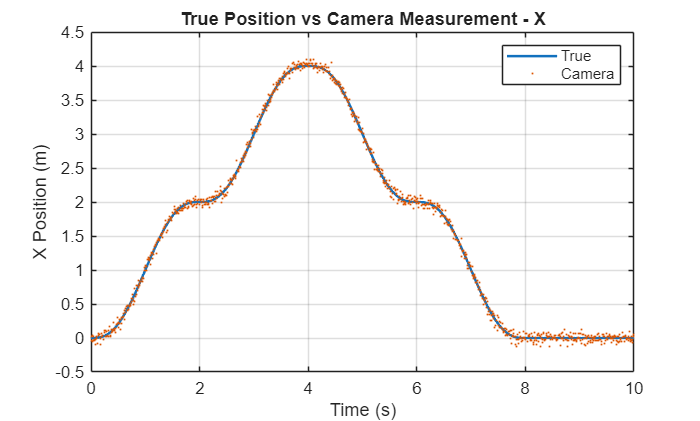

figure;

plot( ...
    t, ...
    p_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    p_camera(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('X Position (m)');

title('True Position vs Camera Measurement - X');

legend( ...
    'True', ...
    'Camera');

grid on;

### True 3D Trajectory vs Camera Measurements

The blue line is the desired/true path:


$$\textrm{ptrue}\left(t\right)=\left\lbrack \textrm{xtrue}\left(t\right),\textrm{ytrue}\left(t\right),\textrm{ztrue}\left(t\right){\left.\right\rbrack }^T \right.$$


while the orange points are:


$$\mathrm{pcamera}\left(t\right)=\mathrm{ptrue}\left(t\right)+\mathrm{np}\left(t\right)$$


The camera does not reconstruct the exact trajectory. It provides an imperfect measurement clustered around the actual trajectory.

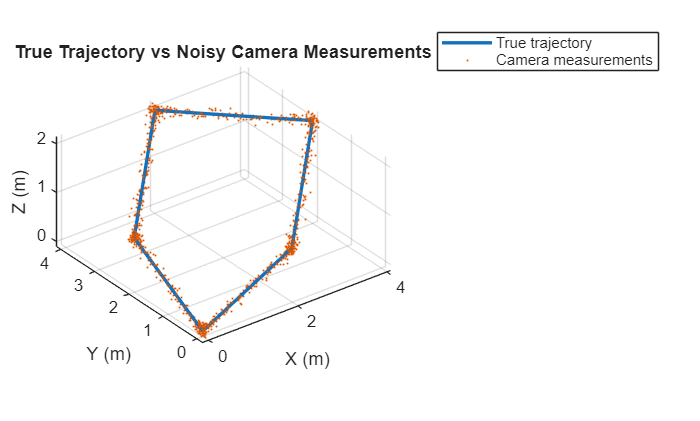

figure;

plot3( ...
    p_true(:,1), ...
    p_true(:,2), ...
    p_true(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_camera(:,1), ...
    p_camera(:,2), ...
    p_camera(:,3), ...
    '.', ...
    'MarkerSize',3);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('True Trajectory vs Noisy Camera Measurements');

legend( ...
    'True trajectory', ...
    'Camera measurements');

### True Specific Force vs IMU Measurement

The blue curve is the **true body-frame specific force**:


$$\textrm{fb}=\textrm{RtrueT}\left(\textrm{atrue}-g\right)$$


and the orange points are the simulated accelerometer:


$$\mathrm{aIMU}=\mathrm{fb}+\mathrm{ba}+\mathrm{na}$$


�

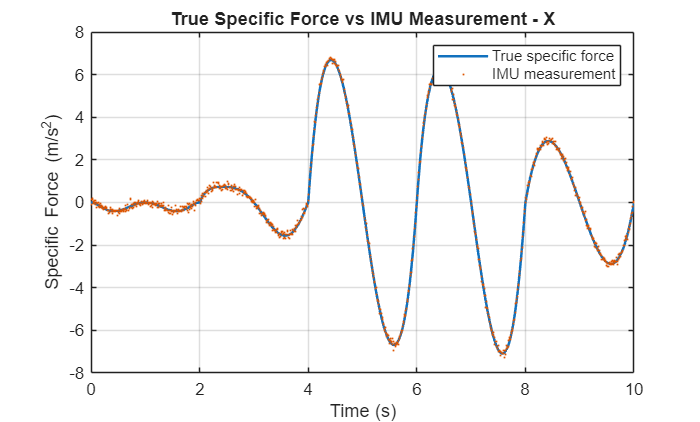

%% 13. Plot True Specific Force vs IMU

% Calculate true body-frame specific force
specific_force_true = zeros(numSamples,3);

for k = 1:numSamples

    specific_force_true(k,:) = ...
        (R_true(:,:,k)' * ...
        (a_true(k,:)' - g))';

end


figure;

plot( ...
    t, ...
    specific_force_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    a_imu(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('Specific Force (m/s^2)');

title('True Specific Force vs IMU Measurement - X');

legend( ...
    'True specific force', ...
    'IMU measurement');

grid on;

### True vs IMU Angular Velocity

The blue curve is:


$$\omega \mathrm{true},x\left(t\right)$$


and the orange points are:


$$\omega \mathrm{IMU}=\omega \mathrm{true}+\mathrm{bg}+\mathrm{ng}$$


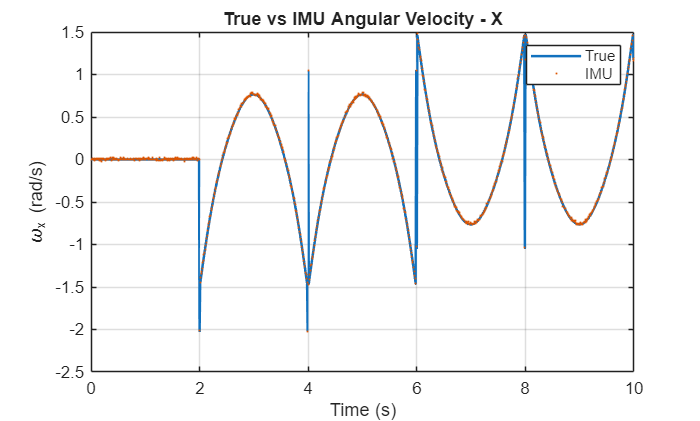

figure;

plot( ...
    t, ...
    omega_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    omega_imu(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('\omega_x (rad/s)');

title('True vs IMU Angular Velocity - X');

legend( ...
    'True', ...
    'IMU');

grid on;



%% 15. Calculate Camera Position Noise RMS

position_error = ...
    p_camera - p_true;

camera_position_rms = ...
    sqrt(mean(position_error(:).^2));


%% 16. Calculate Accelerometer Noise RMS

acceleration_noise_error = ...
    zeros(numSamples,3);

for k = 1:numSamples

    acceleration_noise_error(k,:) = ...
        a_imu(k,:) ...
        - specific_force_true(k,:) ...
        - accel_bias;

end

accelerometer_noise_rms = ...
    sqrt(mean(acceleration_noise_error(:).^2));


%% 17. Calculate Gyroscope Noise RMS

gyro_bias_matrix = ...
    repmat(gyro_bias,numSamples,1);

gyro_noise_error = ...
    omega_imu ...
    - omega_true ...
    - gyro_bias_matrix;

gyroscope_noise_rms = ...
    sqrt(mean(gyro_noise_error(:).^2));



$$\text{True trajectory}
\rightarrow
\begin{cases}
\text{Camera position}+\text{noise}\\
\text{Camera orientation}+\text{noise}\\
\text{Accelerometer}+\text{bias}+\text{noise}\\
\text{Gyroscope}+\text{bias}+\text{noise}
\end{cases}$$


%% 18. Display Sensor Results

fprintf('\n');
fprintf('========================================\n');

fprintf('SYNTHETIC SENSOR RESULTS\n');

SYNTHETIC SENSOR RESULTS


fprintf('========================================\n');


fprintf( ...
    'Camera position noise RMS = %.4f m\n', ...
    camera_position_rms);

Camera position noise RMS = 0.0502 m



fprintf( ...
    'Accelerometer noise RMS = %.4f m/s^2\n', ...
    accelerometer_noise_rms);

Accelerometer noise RMS = 0.1016 m/s^2



fprintf( ...
    'Gyroscope noise RMS = %.4f rad/s\n', ...
    gyroscope_noise_rms);

Gyroscope noise RMS = 0.0101 rad/s




%% 19. Save Step 3 Results

save( ...
    'drone_toy_model.mat', ...
    'waypoints', ...
    'waypointTime', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_camera', ...
    'R_camera', ...
    'a_imu', ...
    'omega_imu', ...
    'sigma_position', ...
    'sigma_camera_angle', ...
    'sigma_acceleration', ...
    'sigma_gyro', ...
    'accel_bias', ...
    'gyro_bias');

fprintf('\nStep 3 results saved to drone_toy_model.mat\n');


Step 3 results saved to drone_toy_model.mat




%% Local Functions

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = logSO3(R)

    cos_theta = ...
        (trace(R)-1)/2;

    cos_theta = ...
        max(-1,min(1,cos_theta));

    theta = ...
        acos(cos_theta);

    if theta < 1e-8

        v = zeros(3,1);

    else

        v = ...
            theta/(2*sin(theta)) * ...
            [
                R(3,2)-R(2,3);
                R(1,3)-R(3,1);
                R(2,1)-R(1,2)
            ];

    end

end
